% Tensor Component Analysis of whole brain using Aya's EEG dataset
% across time and conditions.
clear;

if exist('H:\', 'dir')  % If H:\ exists, assume this is Computer 1
    input_path = 'H:\My Drive\Data\New Data\EEG epoched\';
    output_path = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';

elseif exist('G:\', 'dir')  % If G:\ exists, assume this is Computer 2
    input_path = 'G:\My Drive\Data\New Data\EEG epoched\';
    output_path = 'C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
else
    error('Unknown system: Cannot determine input and output paths.');
end

% 1- ICA on preprocessed epoched data
% - First prototype the pipeline for BLA (baseline auditory condidtion) for
% the first subject. 
% - Import .set file
conditions = {'BLA','BLT', 'P1', 'P2', 'P3'}; %

Processing G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS10.set...


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS10.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


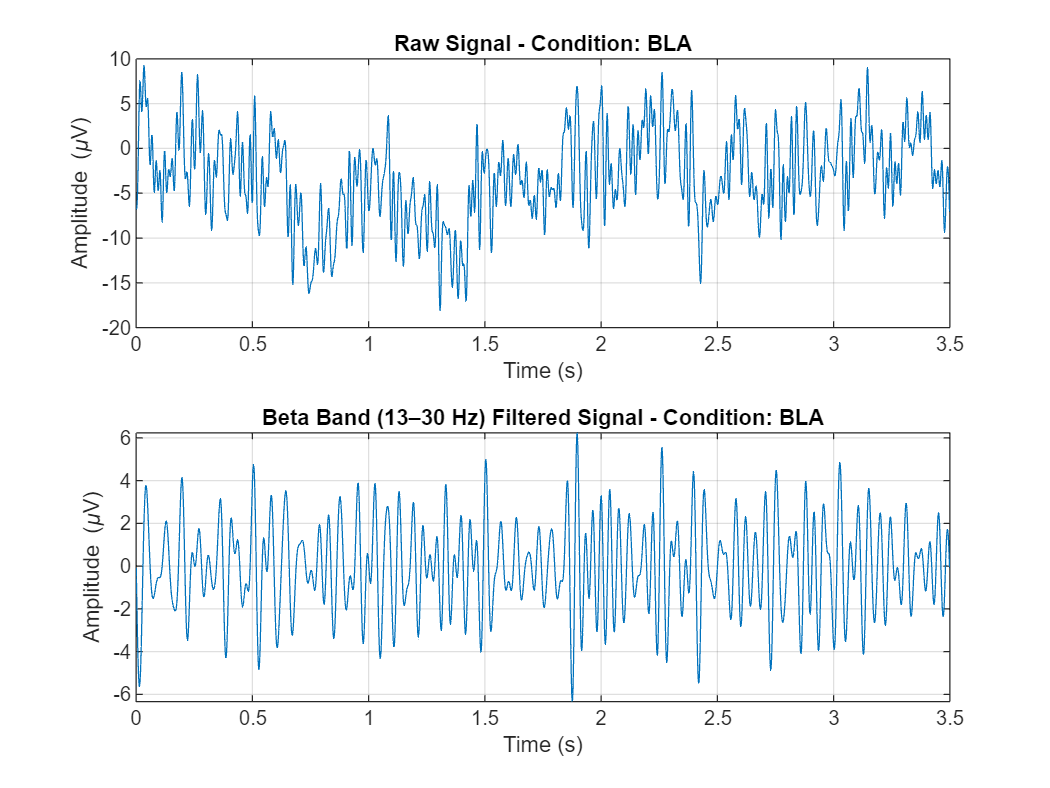

Processing G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS10.set...


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS10.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


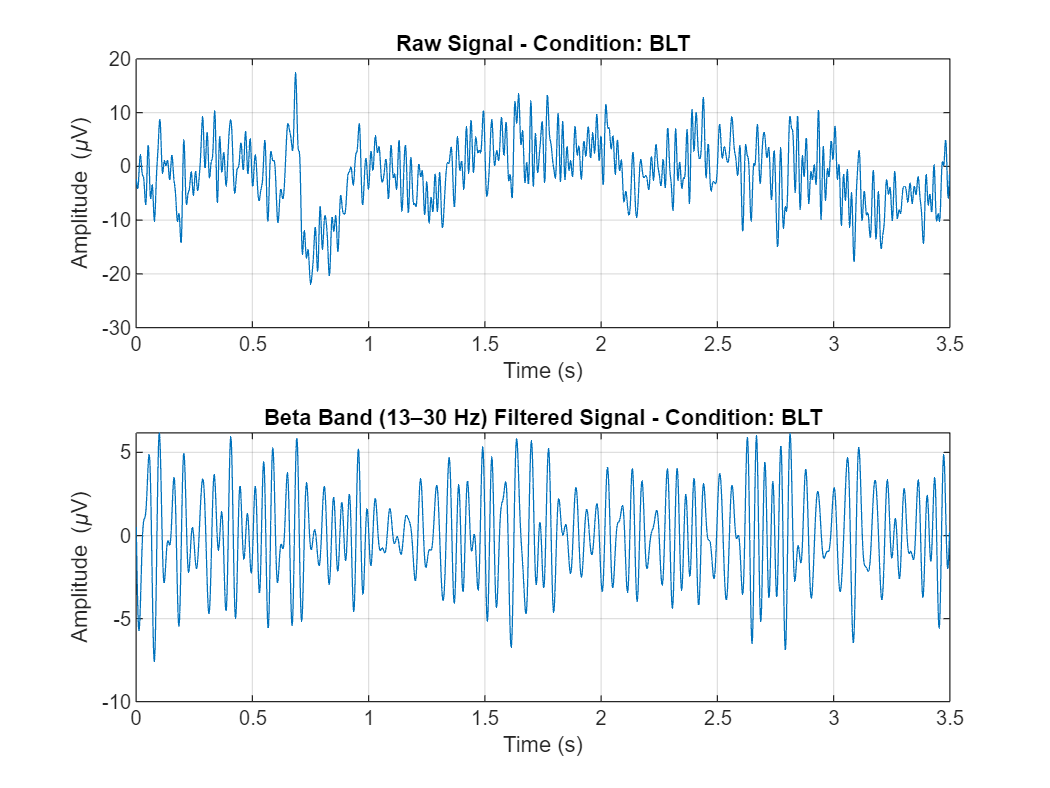

Processing G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS10.set...


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS10.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


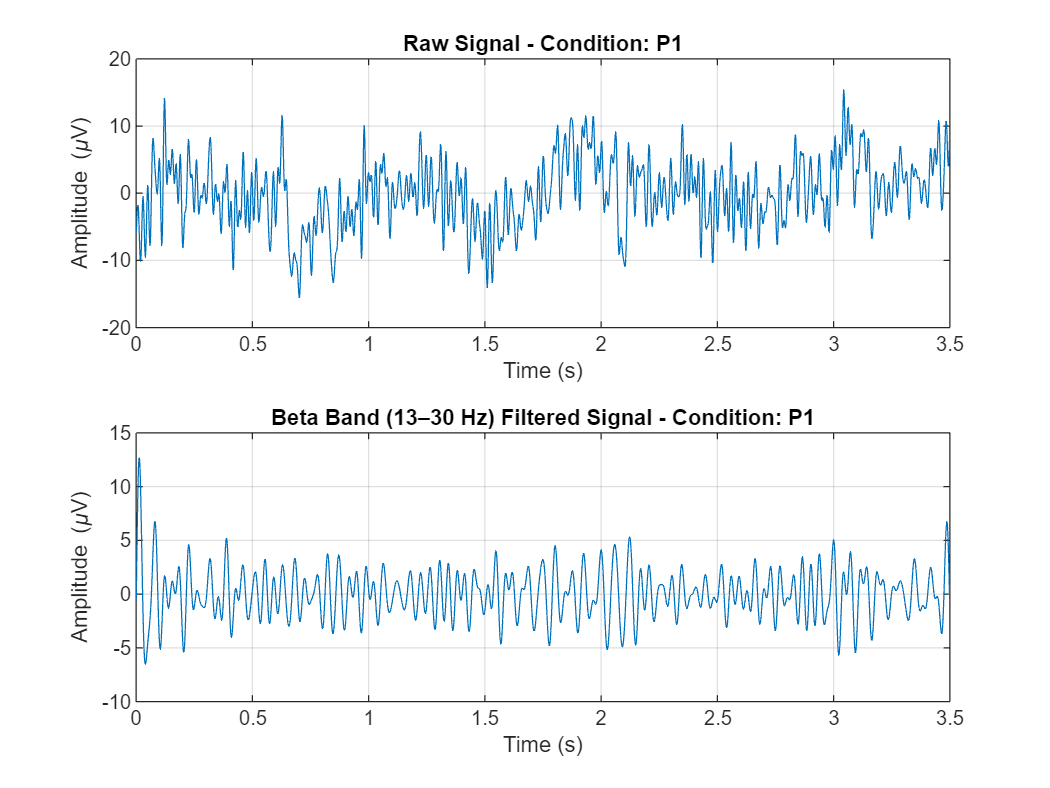

Processing G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS10.set...


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS10.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


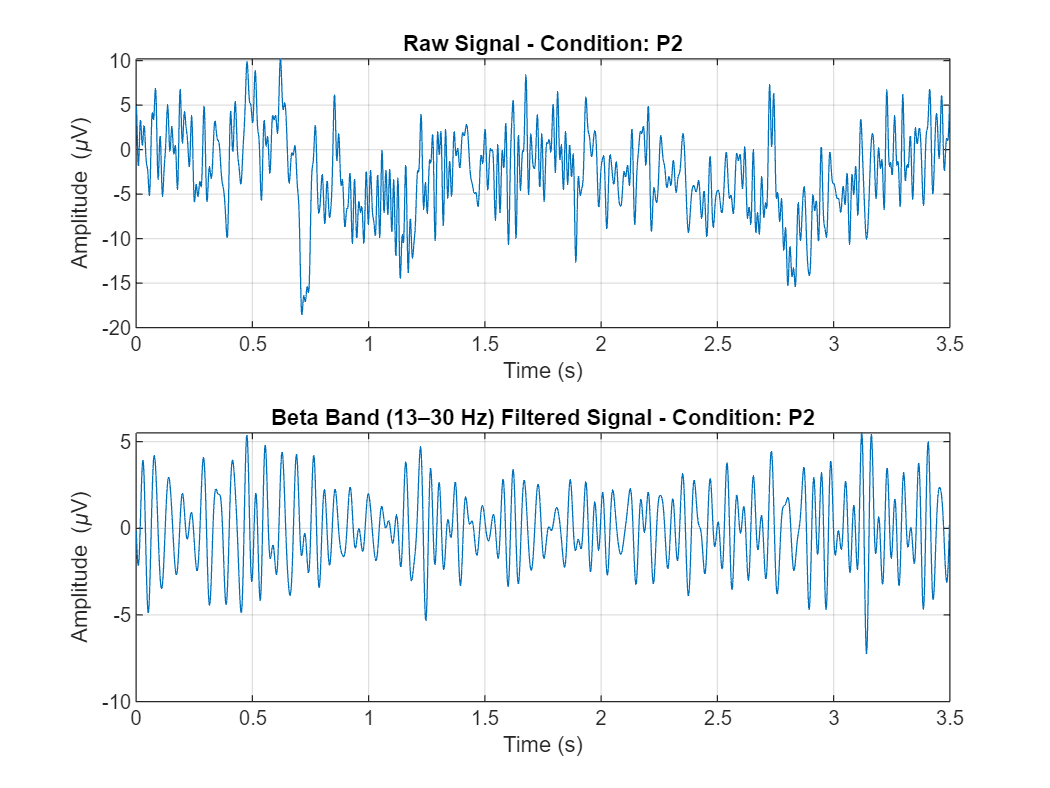

Processing G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS10.set...


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS10.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


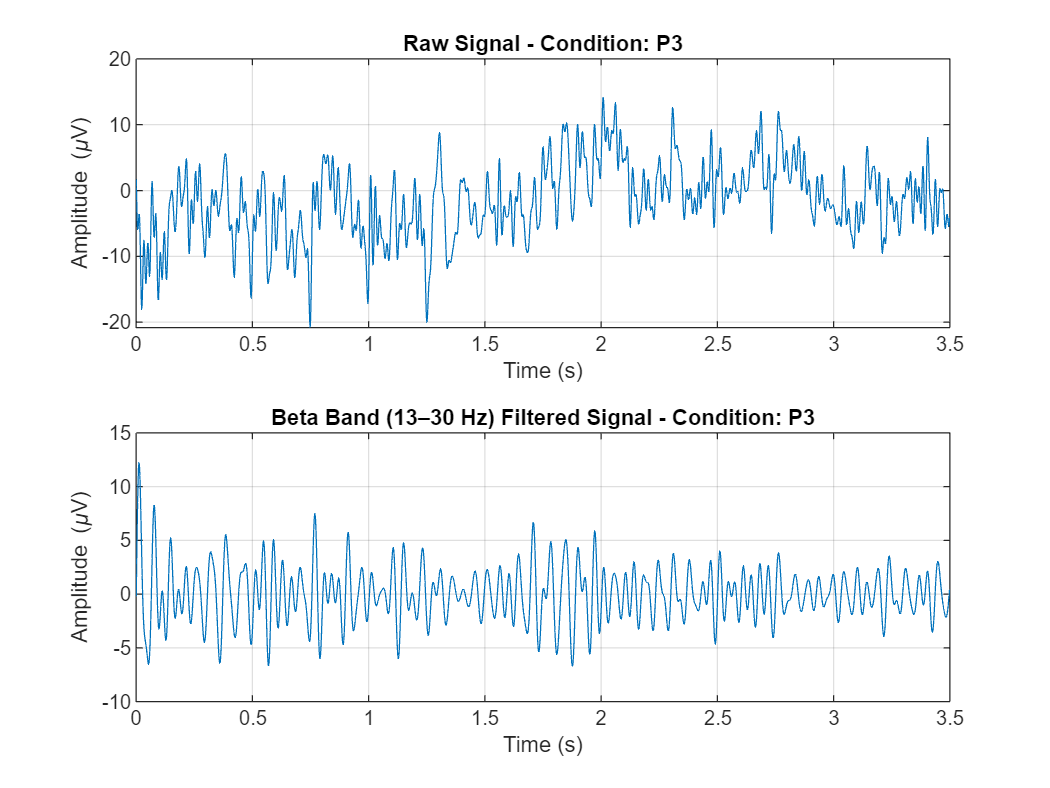

% 2- TCA 
% - 2.1 TCA across condition: making a giant matrix from channel x time x
% trial x condition into ch x time x trial-conidtion)
num_ch= 32; 
num_time_samples = 1792;
num_trials = 60; 
num_conditions = length(conditions);
beta_signal_giant = zeros(num_ch,  num_time_samples , num_trials * num_conditions);
depth_start = 1;
% Loop over each condition
for i = 1:length(conditions)
    condition = conditions{i};
    input_path_condition = fullfile(input_path, condition);
    output_path_condition = fullfile(output_path, condition);
    if strcmp(condition, 'P2')
        excel_file_path = fullfile(input_path,'Indexes for P2.xlsx');
    elseif strcmp(condition, 'P3')
        excel_file_path = fullfile(input_path,'Indexes for P3.xlsx');
    else
        excel_file_path = '';
    end

    if ~exist(output_path_condition, 'dir')
        mkdir(output_path_condition);
    end
    
    % Get all .set files in the directory
    set_files = dir(fullfile(input_path_condition, '*.set'));
    
    % Loop over each subject's dataset
    %for j = 1:length(set_files)
        file_path = fullfile(input_path_condition, set_files(1).name);
        fprintf('Processing %s...\n', file_path);
        EEG = pop_loadset(file_path);
        
        % Extract relevant parameters
        fs = EEG.srate; % Sampling rate
        % time_vector = linspace(-0.5, 3, size(EEG.data, 2)); % Time axis (-500ms to 3000ms)
    
        % Select odd or even epochs based on condition
        if strcmp(condition, 'BLA') || strcmp(condition, 'P1') || strcmp(condition, 'P2') || strcmp(condition, 'P3')
            epoch_trials = 1:2:EEG.trials; % Odd epochs
        elseif strcmp(condition, 'BLT')
            epoch_trials = 2:2:EEG.trials; % Even epochs
        else
            error('Condition not recognized. Please specify "BLA" or "BLT".');
        end
    
        num_trials = length(epoch_trials);
        data = EEG.data(:, :, epoch_trials);
    
        % Bandpass filter beta band (13-30 Hz)
        beta_band = [13 30];
        beta_signal = zeros(size(data)); % Preallocate
        for epoch = 1:size(data, 3)
            beta_signal(:,:,epoch) = bandpass(data(:,:,epoch)', beta_band, fs)';
        end
        
        % Plot one trial (e.g., the first trial) from one channel (e.g., channel 1) for visualization
        trial_to_plot = 1;
        channel_to_plot = 18;
        
        raw_signal = squeeze(data(channel_to_plot, :, trial_to_plot));
        filtered_signal = squeeze(beta_signal(channel_to_plot, :, trial_to_plot));
        time_vector = (0:length(raw_signal)-1) / fs;  % assuming time starts at 0
        
        figure('Name', ['Condition: ' condition], 'NumberTitle', 'off');
        subplot(2,1,1);
        plot(time_vector, raw_signal);
        title(['Raw Signal - Condition: ' condition]);
        xlabel('Time (s)');
        ylabel('Amplitude (\muV)');
        grid on;
        
        subplot(2,1,2);
        plot(time_vector, filtered_signal);
        title(['Beta Band (13–30 Hz) Filtered Signal - Condition: ' condition]);
        xlabel('Time (s)');
        ylabel('Amplitude (\muV)');
        grid on;

        % beta_signal_reshape = reshape(beta_signal, num_ch,num_time_samples*num_trials );
        beta_signal_giant(:,: ,depth_start: num_trials*i) = beta_signal;
        depth_start = 1+num_trials*i;

end

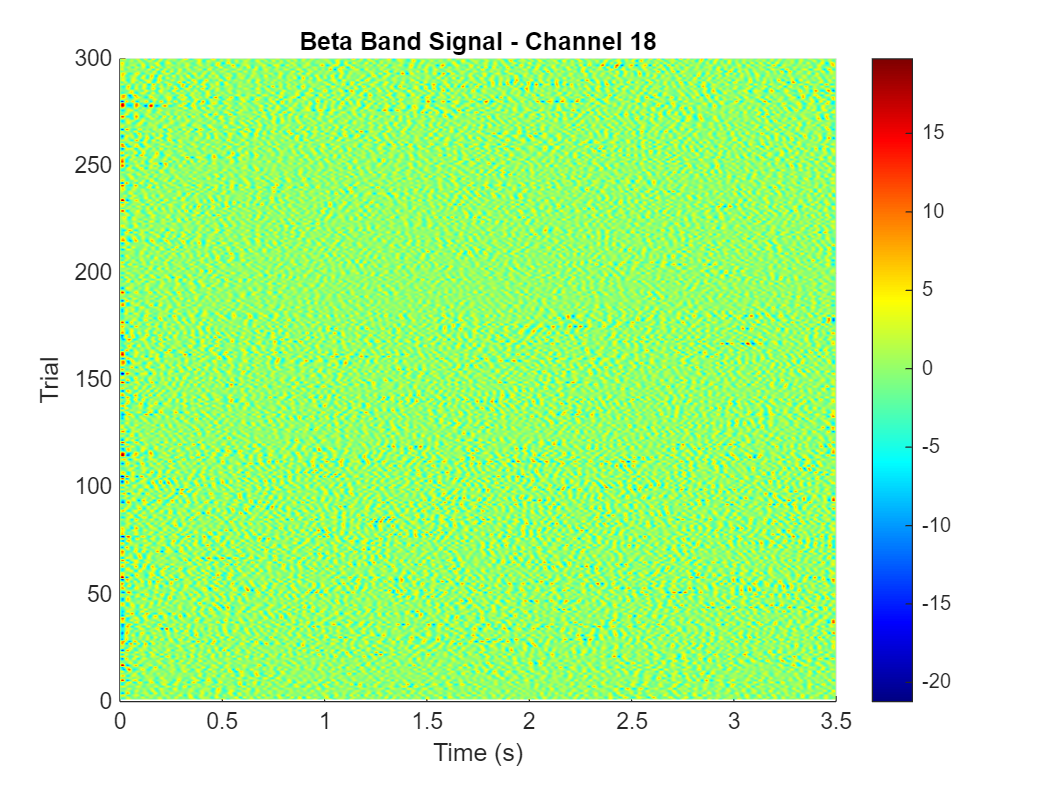


channel_idx = 18;  % Choose the channel to plot
Z = squeeze(beta_signal_giant(channel_idx, :, :));  % [time × trials]

% Transpose Z to [trials × time] if you want trials along y-axis
Z = Z';

% Create time and trial axes
n_time = size(Z, 2);
n_trials = size(Z, 1);
[Time, Trial] = meshgrid((0:n_time - 1)/fs, 1:n_trials);  % Time in seconds

% Plot
figure;
surf(Time, Trial, Z);
xlabel('Time (s)');
ylabel('Trial');
zlabel('Amplitude (\muV)');
title(sprintf('Beta Band Signal - Channel %d', channel_idx));
shading interp;
colorbar;
colormap jet;
view([0 90]);  % Optional: view as 2D heatmap from above

disp(size(beta_signal_giant))

          32        1792         300




% Define the range of components to test
num_components = 1:50;  % Test 1 to 50 components
reconstruction_errors = zeros(size(num_components));
explained_variance = zeros(size(num_components));


if isempty(gcp('nocreate'))
    parpool; % Uses default number of workers
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 8 workers.


parfor idx = 1:length(num_components)
    k = num_components(idx);

    [U, ~] = cpd(beta_signal_giant, k, 'Display', 0);
    reconstructed = cpdgen(U);
    error = norm(beta_signal_giant(:) - reconstructed(:)) / norm(beta_signal_giant(:));
    reconstruction_errors(idx) = error;
    explained_variance(idx) = 1 - error^2;

end

> In cpd_core/state (line 205)
In cpd_core/grad (line 270)
In 

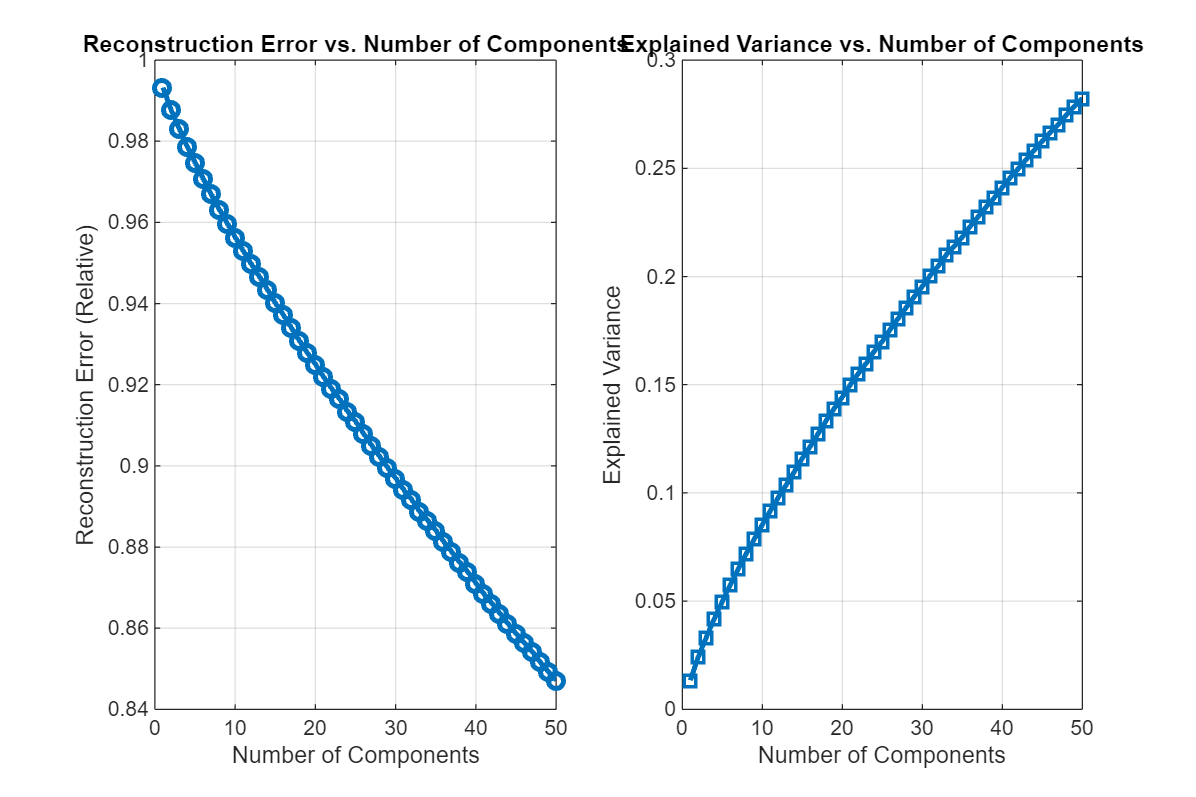

% Plot reconstruction error
figure('Position', [100, 100, 1500, 1000]); % [x, y, width, height]
subplot(1,2,1)
plot(num_components, reconstruction_errors, 'o-', 'LineWidth', 2);
xlabel('Number of Components');
ylabel('Reconstruction Error (Relative)');
title('Reconstruction Error vs. Number of Components');
grid on;

% Plot explained variance
subplot(1,2,2)
plot(num_components, explained_variance, 's-', 'LineWidth', 2);
xlabel('Number of Components');
ylabel('Explained Variance');
title('Explained Variance vs. Number of Components');
grid on;

% Let's not do it across conditions with one giant matrix. Let's do it per
% condition
beta_signal_BLA = beta_signal_giant(:,:,1:60);
disp(size(beta_signal_BLA));

          32        1792          60



% Define the range of components to test
num_components = 1:50;  % Test 1 to 50 components
reconstruction_errors_BLA = zeros(size(num_components));
explained_variance_BLA = zeros(size(num_components));


if isempty(gcp('nocreate'))
    parpool; % Uses default number of workers
end

parfor idx = 1:length(num_components)
    k = num_components(idx);

    [U_BLA, ~] = cpd(beta_signal_BLA, k, 'Display', 0);
    reconstructed_BLA = cpdgen(U_BLA);
    error_BLA = norm(beta_signal_BLA(:) - reconstructed_BLA(:)) / norm(beta_signal_BLA(:));
    reconstruction_errors_BLA(idx) = error_BLA;
    explained_variance_BLA(idx) = 1 - error_BLA^2;

end

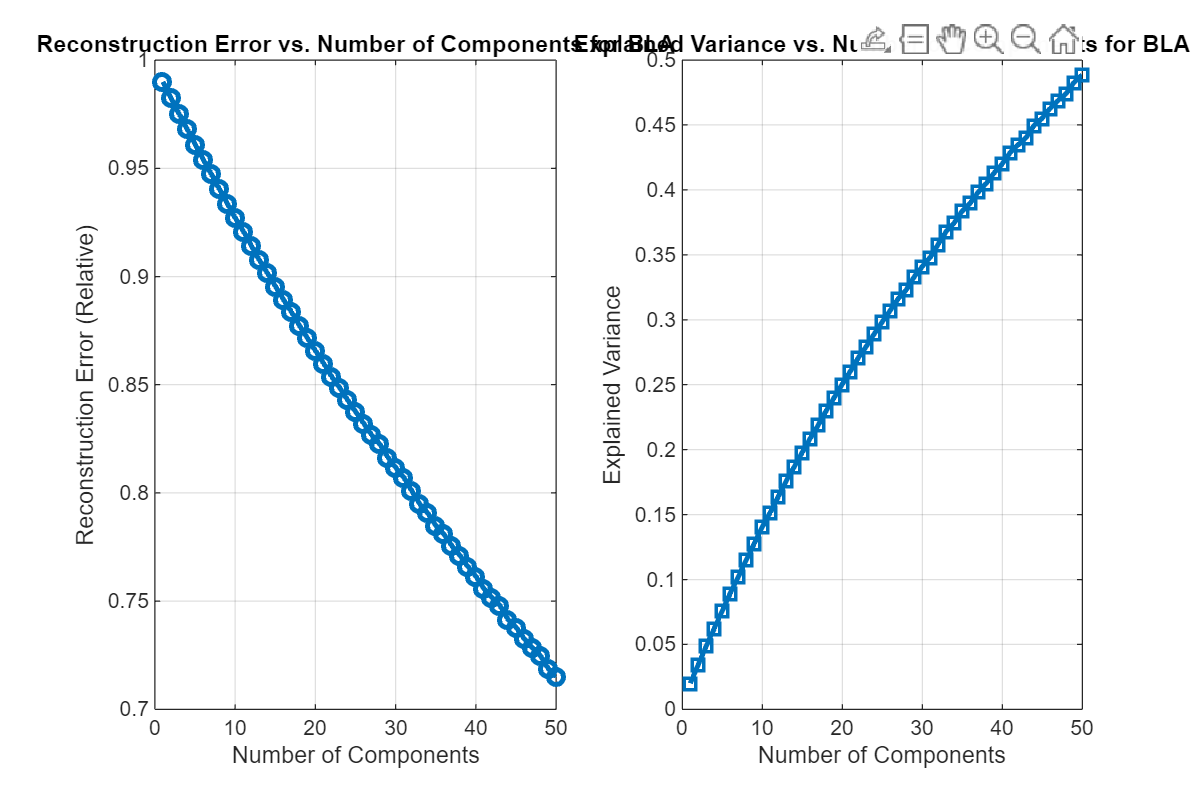

% Plot reconstruction error
figure('Position', [100, 100, 1500, 1000]); % [x, y, width, height]
subplot(1,2,1)
plot(num_components, reconstruction_errors_BLA, 'o-', 'LineWidth', 2);
xlabel('Number of Components');
ylabel('Reconstruction Error (Relative)');
title('Reconstruction Error vs. Number of Components for BLA');
grid on;

% Plot explained variance
subplot(1,2,2)
plot(num_components, explained_variance_BLA, 's-', 'LineWidth', 2);
xlabel('Number of Components');
ylabel('Explained Variance');
title('Explained Variance vs. Number of Components for BLA');
grid on;